[gfile, path] = uigetfile('*.csv','Pick .csv file for GCAMP signal');
gdirpath = fullfile(path,gfile);

G = readtable(gdirpath);

ref = G.AnalogIn__Ch_1AIn_1_Dem_AOut_1_(:);
sig = G.AnalogIn__Ch_1AIn_1_Dem_AOut_2_(:);
time = G.Time_s_(:);

fs = round( 1/median(diff(time))); %calculates the sampling frequency

bleachingFilter = designfilt('lowpassiir', 'HalfPowerFrequency', 1, 'SampleRate', fs, 'DesignMethod', 'butter', 'FilterOrder', 12);
rLowpass = filtfilt(bleachingFilter, ref);
sLowpass = filtfilt(bleachingFilter, sig);      

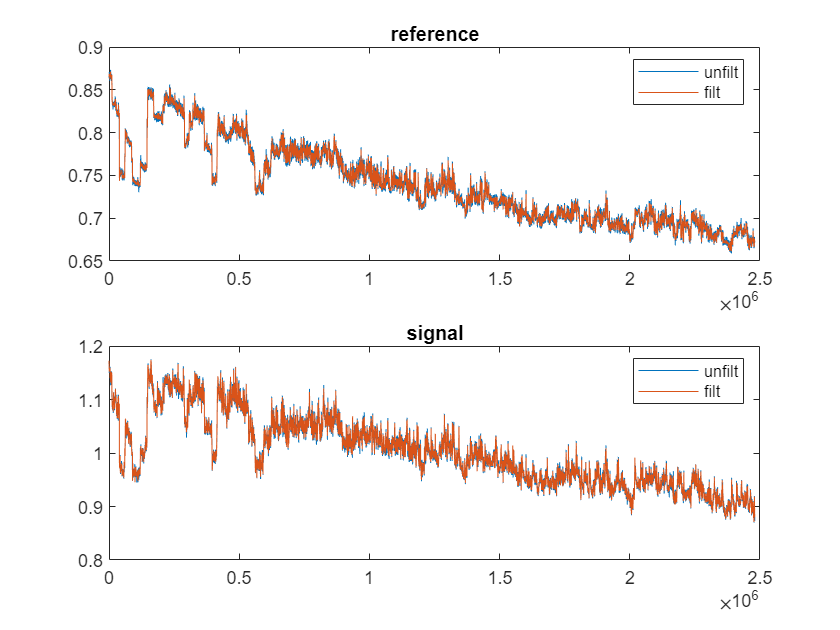

clf
subplot(211)
plot(ref)
hold all
plot(rLowpass)
legend({'unfilt','filt'})
title('reference')
subplot(212)
plot(sig)
hold all
plot(sLowpass)
legend({'unfilt','filt'})
title('signal')

rFit = fit(time, rLowpass, fittype('exp1'));
sFit = fit(time, sLowpass, fittype('exp1'));
rBleaching = rFit(time);
sBleaching = sFit(time);
rCorrected = ref - rBleaching;
sCorrected = sig - sBleaching;

f = sCorrected - rCorrected;
ff = filtfilt(bleachingFilter, f);

stim_time = fs*4*60 + fs*50;
subFF = (ff((stim_time-60*5*fs):stim_time+60*fs*5));
[~,noext,~] = fileparts(gfile);


clf
xpatch = [fs*60,fs*60*5,fs*60*5,fs*60];

for i =1:3
    h = subplot(3,1,i)
    plot(totFF(:,i),'LineWidth',0.75)
    xticks(0:fs*60:fs*60*5)
    xticklabels(0:5)
    yvals = ylim()
    ypatch = [yvals(1),yvals(1),yvals(2),yvals(2)]
    Plotter.modSubPlot(h,8,'w')
    xlabel('Time (min)')
    ylabel('Fluorescence (a.u.)')
    patch(xpatch,ypatch,'red','FaceAlpha',.15,'EdgeColor','none')
    box off
end


